clc;
clear all;
l=1;
k1=2.9190;
k2=0;
% f=deg2rad([10;-30.32;30.32]);
f = [3.1065,0.4111,1.2902];
% f = [phi_1_subs,phi_2_subs,phi_3_subs];
x_0=[l*cos(f(1));l*sin(f(1));l*cos(f(1))+l*cos(f(1)+f(2));l*sin(f(1))+l*sin(f(1)+f(2));l*cos(f(1))+l*cos(f(1)+f(2))+l*cos(f(1)+f(2)+f(3));l*sin(f(1))+l*sin(f(1)+f(2))+l*sin(f(1)+f(2)+f(3));f(1);f(2);f(3)];
tspan=0:.1:300;
[t,X]=ode45(@(t,X) foot(X,l,k1,k2),tspan,x_0);
X1=[zeros(length(tspan),1) X(:,1) X(:,3) X(:,5)];
X2=[zeros(length(tspan),1) X(:,2) X(:,4) X(:,6)];
for i=1:3
    p1(:,i)=X1(:,i+1)-X1(:,i);
    p2(:,i)=X2(:,i+1)-X2(:,i);
end
for i=1:3
s1(:,i)=sqrt(p1(:,i).^2+p2(:,i).^2);
end
figure()

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

x_corr_end = X(:,5);
y_corr_end = X(:,6);
arr_diff = sqrt((x_corr_end(:)-k1).^2+(y_corr_end(:)).^2);
arr_diff(9)-arr_diff(8)

ans = 0.0041

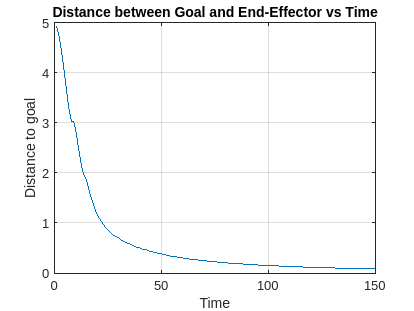

% Generate indices for the array
indices = 1:length(arr_diff)/20;

% Plot array against indices
plot(indices, arr_diff(indices))
grid on;
% Add labels and title
ylabel('Distance to goal')
xlabel('Time')
title('Distance between Goal and End-Effector vs Time')

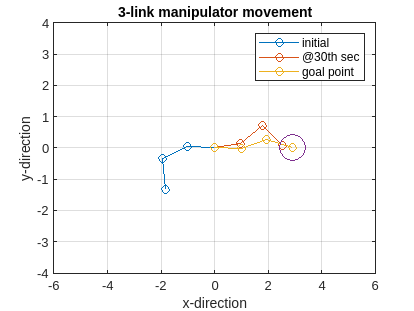

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

plot(X1(1,:),X2(1,:),'-o')
hold on
 plot(X1(51,:),X2(51,:),'-o')
% hold on
% plot(X1(151,:),X2(151,:),'-o')
% hold on
% plot(X1(251,:),X2(251,:),'-o')
% hold on
plot(X1(3000,:),X2(3000,:),'-o')
hold on
plot(k1,k2,'o','MarkerSize',20)

xlim([-6,6]);
ylim([-4,4])
title('3-link manipulator movement')
xlabel('x-direction')
ylabel('y-direction')
legend('initial','@30th sec','goal point')
grid on

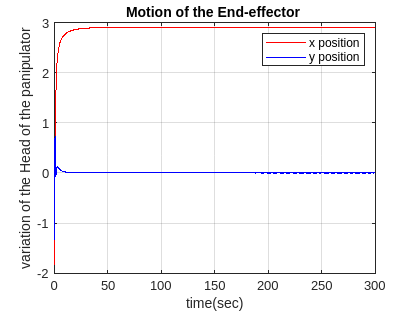



figure()
plot(t,X(:,5),'r',t,X(:,6),'b')
title('Motion of the End-effector ')
xlabel('time(sec)')
ylabel('variation of the Head of the panipulator')
legend('x position','y position')
grid on